## **AERO40003 Computing and Numerical Methods 1**

## **Coursework Project 2019-2020**

## **Dr. Maria Ribera Vicent & Dr. Elnaz Naghibi**

## **Due Date: 20 March 2020**

# PART 2 - NUMERICAL METHODS  [50%]

### **Question 1 [10%]**

Plot the function $f\left(x\right)=\mathrm{cos}\;x\;\left(e^{2x} -2e^x +1\right)$ in the interval $\left\lbrack -\pi /4,3\pi /4\right\rbrack$ and find its two roots in the mentioned interval using MATLAB functions.

Using the derivative of the function and appropriate initial guesses from the plot of the function, verify which root can be found by fixed-point method. Use the fixed-point method to approximate this root and use the secant method to find the other root (for which the fixed-point method does not work). Show the convergence to each root using appropriate plots and provide the codes for both methods.  Consider the tolerance value to be equal to 1e-6.

**Answer:**

You can use this space to explain the answers and include equations as needed using either Latex code or the live script equation editor from the tab "insert".

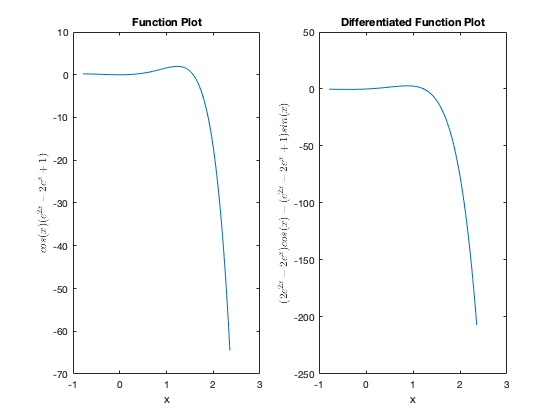

% Use this box for coding. 
% Outputs and graphs will be displayed on the right panel.
% To avoid submitting multiple files, please include functions at the bottom of your scripts.

%setup
clc
clear

%symbolic function anf range setup
syms x
x_values = linspace(-pi()/4, 3*pi()/4,200);
original_function = cos(x).*(exp(2.*x)-2.*exp(x)+1);


%function results
y_values = double(subs(original_function, x, x_values));

%differentiated function
differentiated_original_function = diff(original_function);

%differentiated function results
y_values_differentiated_original_function = double(subs(differentiated_original_function,x,x_values));


%plotting function
figure;

subplot(1,2,1)
plot(x_values,y_values)
title("Function Plot")
xlabel("x")
ylabel({"$cos(x)(e^{2x}-2e^{x}+1)$"}, 'Interpreter','latex')

subplot(1,2,2)
plot(x_values,y_values_differentiated_original_function)
title("Differentiated Function Plot")
xlabel("x")
ylabel("$(2e^{2x}- 2e^{x})cos(x) - (e^{2x}-2e^{x}+1)sin(x)$", 'Interpreter','latex')


%roots of the function within the range
roots = solve(original_function);
root_1 = roots(1);
root_2 = roots(2);
fprintf("The roots are %e and %i",root_1, root_2);

The roots are 1.570796e+00 and 0







%secant methond to find one root
tic
secant_solution = secant(original_function, 1.5,1.6);
toc

Elapsed time is 0.093217 seconds.


fprintf("The root found by the secant approach is %e",secant_solution);

The root found by the secant approach is 1.570796e+00


tic
func_ = matlabFunction(original_function);
f_n0 = func_(1.5);
f_n1 = func_(1.6);
solution =  1;
n0 = 1.5;
n1 = 1.6;
count = 0;
while abs(f_n1) > 10^(-6)
    solution = n1 - f_n1*((n1 - n0)/(f_n1 - f_n0));
    f_n0 = f_n1;
    n0 = n1;
    n1 = solution;
    f_n1 = func_(solution);
    count = count + 1;
end
toc

Elapsed time is 0.145522 seconds.


disp(count)

     4



fprintf("The root found by the secant approach is %e",solution);

The root found by the secant approach is 1.570796e+00











%fixed point method to find one root
test_func = log(2*exp(x)-1)/2;
tic
fixed_point_solution = fixed_point(test_func, 0.5);
toc

Elapsed time is 0.144592 seconds.


fprintf("The root found by the fixed point approach %e", fixed_point_solution)

The root found by the fixed point approach 1.413338e-03





recast_function = matlabFunction(log(2*exp(x)-1)/2);
tic
fixed_point_solution = 0.5;
x1 = 0;
count = 0;
while abs(fixed_point_solution-x1)>10^-6
    x1 = fixed_point_solution;
    fixed_point_solution = recast_function(fixed_point_solution);
    count = count + 1;
end
toc

Elapsed time is 0.089126 seconds.


disp(count)

        1417



fprintf("The root found by the secant approach is  %e",fixed_point_solution)

The root found by the secant approach is  1.413338e-03

### **Question 2 [20%]**

**Part a: [10 %]**

Calculate Legendre polynomial of degree 5 using equation 16 in Handout_4 and MATLAB symbolic toolbox. Compare your resulting polynomial with "legendreP" function in MATLAB. Plot this function in the interval $\left\lbrack -1,1\right\rbrack$ and calculate its roots $\eta_i$. Calculate weighting coefficients $w_i$ using the definition in equation 21. Using  $\eta_i$ and $w_i$, calculate the integral of  $\int_{-2}^1 \left({\textrm{ax}}^9 +{\textrm{bx}}^5 +{\textrm{cx}}^2 \right)\;\textrm{dx}$ and show that it will be the same as its analytical value.

**Answer:**

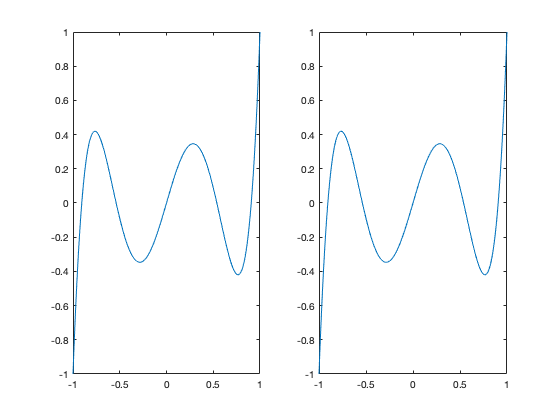

%setup
clc
clear

%legendre polynomial
syms x
analytical_solution = legendre_polynomial(5);
matlab_solution = legendreP(5,x);


%plotting the two solutions
x_values = linspace(-1,1,200);
y_values_analytical = double(subs(analytical_solution, x, x_values));
y_values_matlab = double(subs(matlab_solution,x,x_values));

figure;
subplot(1,2,1)
plot(x_values,y_values_analytical)

subplot(1,2,2)
plot(x_values,y_values_matlab)


%roots
roots = double(solve(matlab_solution));


%weigths
legendre_polynomial_differentiated = matlabFunction(diff(analytical_solution,x));
weights = 2./(1-roots.^2).*(legendre_polynomial_differentiated(roots).^(-2));

%solution to integral
syms  x a b c
func_ = matlabFunction(((a.*(-1/2)+(3/2).*x).^9 + b.*((-1/2)+(3/2).*x).^5 + c.*((-1/2)+(3/2).*x).^2).*(3/2));
solution =  sum(weights.*func_(1,1,1,roots))

solution = -109.8000

%
%
syms x
i = x^9 + x^5 + x^2;
matlab_solution = vpaintegral(i, x,[-2 1])

$$matlab\_solution = -109.8$$

**Part b: [10 %]**

Use Simpson integration scheme to calculate the below integral for $n=20,40,80$. Compare the results with the analytical value and calculate the error in each case. Provide the code for the integration scheme and error calculation.


$$\int_0^{\frac{3\pi }{2}} \textrm{x}\;\textrm{sinx}\;\textrm{dx}$$


**Answer:**

%setup
clc
clear 

%analytical answer
analytical_solution = -1;

%variables
n_2 = [20,40,80];
tic
solution=zeros(1,3);
errors=zeros(1,3);
count = 1;
func = @(x) x.*sin(x);
for i = n_2
    b = i+1;
    vector = transpose([1,mod(1:b-2,2)*2 + 2,1]);
    h = ((3*pi()/2)/i);
    x_values = linspace(0,3*pi()/2,b);
    h_3 = h/3;
    
    
    
    %function solutions
    y_values =  transpose(func(x_values));
    
    
    %estimate
    
    solution(count)= h_3*sum(y_values.*vector);
    errors(count) = abs(-1 - solution(count));
    count = count + 1;
end
solution

solution =    -0.9999   -1.0000   -1.0000


errors

errors = 	1.0e+-4 *

    0.5194    0.0322    0.0020


toc

Elapsed time is 0.049427 seconds.



tic
analytical = -1;
b_2 = n_2+1;
h_2 = ((3*pi()/2)./n_2)./3;
c = num2cell(b_2);
vector_2 = cellfun(@(v) [1,mod(1:v-2,2)*2+2,1],c,'UniformOutput', false);
y_values_2 = cellfun(@(l) linspace(0,3*pi()/2,l) ,c,'UniformOutput',false);
y_values_2 = cellfun(@(x) x.*sin(x),y_values_2,'UniformOutput',false);
solutions = h_2.*[(sum(vector_2{1}.*y_values_2{1})),(sum(vector_2{2}.*y_values_2{2})),(sum(vector_2{3}.*y_values_2{3}))]

solutions =    -0.9999   -1.0000   -1.0000


error = abs(analytical - solution)

error = 	1.0e+-4 *

    0.5194    0.0322    0.0020


toc

Elapsed time is 0.070954 seconds.


### **Question 3 [20%]**

**Part a: [10%]**

Use Chebyshev distribution to sample 5 values of function $f\left(x\right)=\frac{1}{\mathrm{cosh}\;x}$ in the interval $\left\lbrack -1,1\right\rbrack$. Write a code to calculate the Lagrange interpolating polynomial passing though these points. Increase the number of points to 15 and rebuild the polynomial. Provide graphs to compare the original function and the interpolating polynomial and report the Euclidean norm of error in each case. 

**Answer:**

%test case
x_values = linspace(-1,1);
y_values = 1./cosh(x_values);

%plotting
figure;
hold on
plot(x_values, y_values)


%data points
N = 4;
i = 0:1:N;
chev_ = -cos(((2.*i + 1)./(2*N + 2)).*pi());
y_values = 1./cosh(chev_)

y_values =     0.6723    0.8491    1.0000    0.8491    0.6723


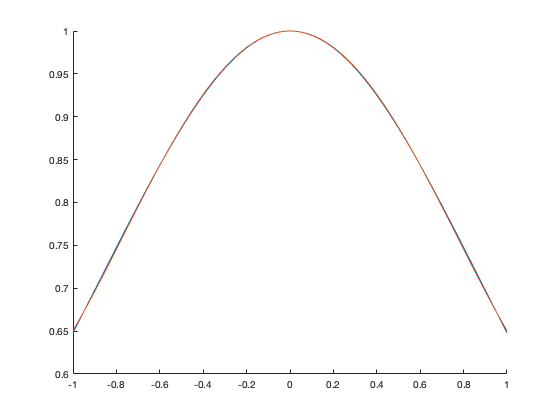


%lagrange polynomial
syms x 
y_l = cell(1,N+1);
for count=1:N+1
    k =chev_(count);
    chev = chev_;
    chev(count) = [];
    top = x - chev;
    bottom = k - chev;
    p_top =  prod(top);
    p_bottom = prod(bottom);
    l = p_top/p_bottom;
    y_l{1,count} = l*y_values(count);
end
y_l;
x = 0;
for i = 1:N+1;
    x = x + y_l{1,i};
end
test = matlabFunction(x);
x_ = linspace(-1,1);
y_ = test(x_);
plot(x_,y_)

**Part b: [10%]**

Use the 5 equally spaced sample points for the function in part a and find the cubic splines passing through these points. Calculate the Euclidean norm of the error in this case and provide a graph to compare the original function and the cubic splines.

**Answer:**

%points
x_values = linspace(-1,1,5)

x_values =    -1.0000   -0.5000         0    0.5000    1.0000


x_test_1 = linspace(-1,-0.5);
x_test_2 = linspace(-0.5,0);
x_test_3 = linspace(0,0.5);
x_test_4 = linspace(0.5,1);
y_values = 1./cosh(x_values)

y_values =     0.6481    0.8868    1.0000    0.8868    0.6481


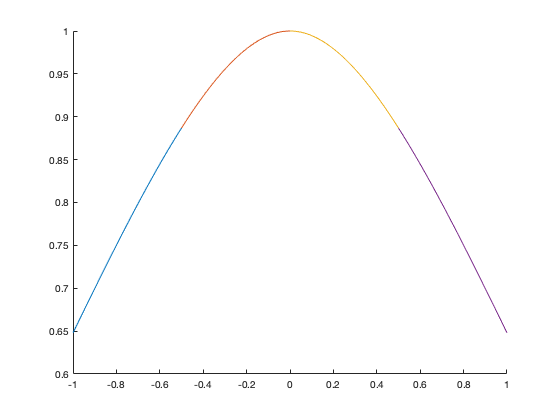

%y_test = 1./cosh(x_test);
dx  = x_values(2) - x_values(1);

%displaying plots
figure;
hold on
%plot(x_test, y_test)

%creating elements for coeficient matrix
n = length(x_values)-2;
A = zeros(n,n);
A_1 = ones(1,n)*(2/3);
A_2 = ones(1,n-1)*(1/6);
A =  diag(A_1);
A(n+1:n+1:end-1) = A_2;
A(2:n+1:end-3) = A_2;

%creating boundary matrix
boundary = zeros(n,1);
for i=1:1:n
    boundary(i) = (y_values(i+2) - (2*y_values(i+1)) + y_values(i))/(dx^2);
end

%finding second derivatives
y2 = [0,transpose(inv(A)*boundary),0];

syms x
c = cell(1,n+1);
for i=1:n+1
    
    equation_1 = (y2(i)/6)*(((x_values(i+1)-x)^3/(x_values(i+1)-x_values(i)))-(x_values(i+1)-x_values(i))*(x_values(i+1)-x));
    
    equation_2 = (y2(i+1)/6)*(((x - x_values(i))^3/(x_values(i+1)- x_values(i)))-((x_values(i+1)-x_values(i))*(x-x_values(i))));
    
    equation_3 = y_values(i)*((x_values(i+1)-x)/(x_values(i+1)- x_values(i)));
    
    equation_4 = y_values(i+1)*( (x-x_values(i))/(x_values(i+1)- x_values(i)));
    
    c{1,i} = matlabFunction(equation_1+equation_2+equation_3+equation_4);
end
test_1 = c{1,1};
test_2 = c{1,2};
test_3 = c{1,3};
test_4 = c{1,4};
plot(x_test_1,test_1(x_test_1))
plot(x_test_2,test_2(x_test_2))
plot(x_test_3,test_3(x_test_3))
plot(x_test_4,test_4(x_test_4))

Error

function error=euclidean(prediction,estimate)

end








## **Secant Method **

Takes 3 arguments secant(function (symbolic), initial prediction number 1 (double), initial prediction number 2 (double))

returns root (double)

function root=secant(func, init_prediction_n0, init_prediction_n1)
func_ = matlabFunction(func);
f_n0 = func_(init_prediction_n0);
f_n1 = func_(init_prediction_n1);
solution =  1;
n0 = init_prediction_n0;
n1 = init_prediction_n1;
while abs(f_n1) > 10^(-6)
    solution = n1 - f_n1*((n1 - n0)/(f_n1 - f_n0));
    f_n0 = f_n1;
    n0 = n1;
    n1 = solution;
    f_n1 = func_(solution);
end
root = solution;
end

## **Fixed Point Method**

takes 2 arguments (function (symbolic), initial prediction (double))

retunrs root (double)

function root=fixed_point(func,init_prediction_x0)
    func_ = matlabFunction(func);
    x0 = init_prediction_x0;
    x1 = 0;
    while abs(x0-x1)>10^-6
        x = x0;
        x1 = x0;
        x0 = func_(x);
    end
    root=x0;
end


function polynomial=legendre_polynomial(degree)
    syms x N
    func =1/(2^N*factorial(N))*diff((x^2-1)^N,x,degree);
    polynomial = subs(func,N,degree);
end